# **Running "unified" imaging pipeline (cnmf segmentation)**

For running this tutorial now:

          [https://github.com/Alvalunasan/U19-pipeline-matlab/tree/UnifiedImagingPipeline](https://github.com/Alvalunasan/U19-pipeline-matlab/tree/UnifiedImagingPipeline)    (checkout UnifiedImagingPipeline branch)

          [https://drive.google.com/drive/folders/1u9-iLoqE63Ra1jVpblupVPyw2oZZ5uTd](https://drive.google.com/drive/folders/1u9-iLoqE63Ra1jVpblupVPyw2oZZ5uTd)      (download this dataset and copy it as "imaging_data" in this folder)

This live scripts introduce how to work with an existing data pipeline, we will cover the following topics:

- Imaging schema structure & prerequisites

- Quick glance on imaging data

- Running an imaging session through the pipeline

"Unified" means for mesoscope & 2 or 3 photon imaging.

**Database connection **

setenv('DB_PREFIX', 'u19_')
dj.conn('datajoint00.pni.princeton.edu');

 0:  datajoint00.pni.princeton.edu via TCP/IP   Server version 5.5.5-10.2.22-MariaDB (encrypted)
database connection id: 74459


## Imaging schema structure & prerequisites

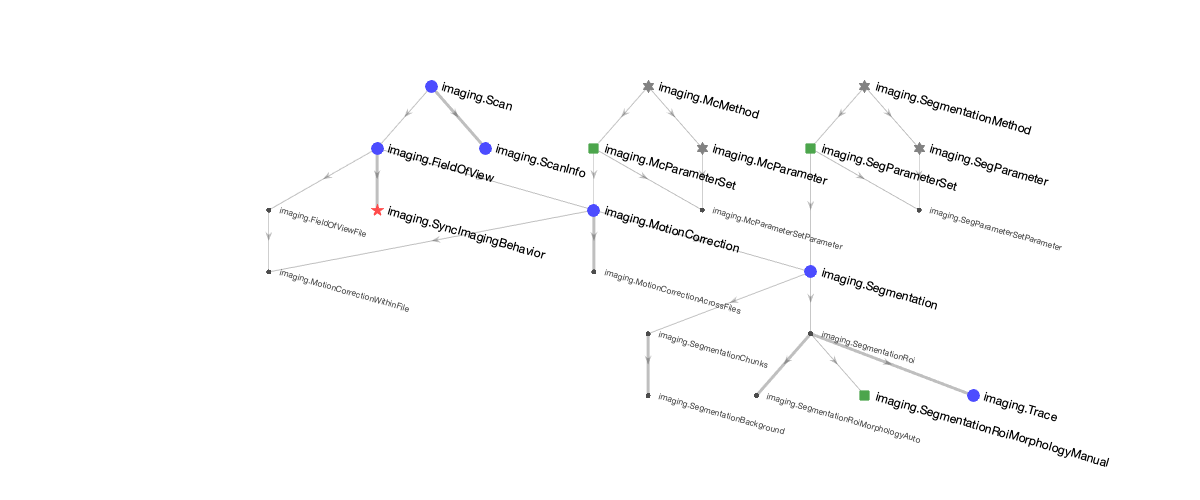

figure
set(gcf,'position',[0,0,1200,500])
erd(imaging.FieldOfView);
erd('imaging')

Main Table description:

- `imaging.Scan: ``Relationship between session & imaging path.`

- `imaging.FieldOfView: ``Meta-info about specific FOV on imaging session. (2/3 photon: single FOV, mesoscope: multiple FOV).`

- `imaging.MotionCorrection: ``Handles a motion correction process for a field of view with a given method and given parameters.`

- `imaging.Segmentation: ``Handles a segmentation process for a motion correction processed session with a given method and given parameters.`

- `imaging.Trace: ``Activity traces for each ROI found in Segmentation process`

___________________

We created an example session for the tutorial:

**subject_fullname**: testuser_imaging_pipe1 **session_date**: 2021-03-02

Check if Session is present on acquisition session

session_key = struct();
session_key.subject_fullname = 'testuser_imaging_pipe1';
session_key.session_date     = '2021-03-02';
session_data = fetch(acquisition.Session & session_key, '*')

session_data = struct with fields:
        subject_fullname: 'testuser_imaging_pipe1'
            session_date: '2021-03-02'
          session_number: 0
      session_start_time: '2016-06-23 15:39:00'
        session_end_time: '2016-06-23 17:13:00'
        session_location: 'Bezos3'
                    task: 'Towers'
                   level: 11
                  set_id: 1
           stimulus_bank: 'C:/Experiments/ViRMEn/experiments/protocols/stimulus_trains_PoissonBlocksCondensed3m_20sets_dup0p5_pan100_n400_x10.mat'
         stimulus_commit: 'c782eb3f7737c2672c66c1b4405e3be569e80db4'
     session_performance: 71.9723
              num_trials: 289
          num_trials_try: 289
       session_narrative: ''
        session_protocol: 'poisson_blocks.m poisson_blocks_reboot_3m.mat PoissonBlocksCondensed3m'
    session_code_version: {[2.1000]  [4]}
          is_bad_session: 0
        session_comments: ''


**Populate Scan table**

populate(imaging.Scan, session_key)


**imaging.Scan: Found 1 unpopulated keys

Populating imaging.Scan for:
    subject_fullname: 'testuser_imaging_pipe1'
        session_date: '2021-03-02'
      session_number: 0

Get all paths from Directory: /Volumes/Bezos-center/RigData/scope/bay3/testuser
Elapsed time is 2.730930 seconds.
directory with files /mnt/bucket/PNI-centers/Bezos/RigData/scope/bay3/testuser/imaging/testuser_imaging_pipe1/20210302 found !!


## Quick glance on imaging data

Data taken from Sue Ann Koay imaging data: 

**subject_fullname**: koay_k53 **session_date**: 2016-06-23

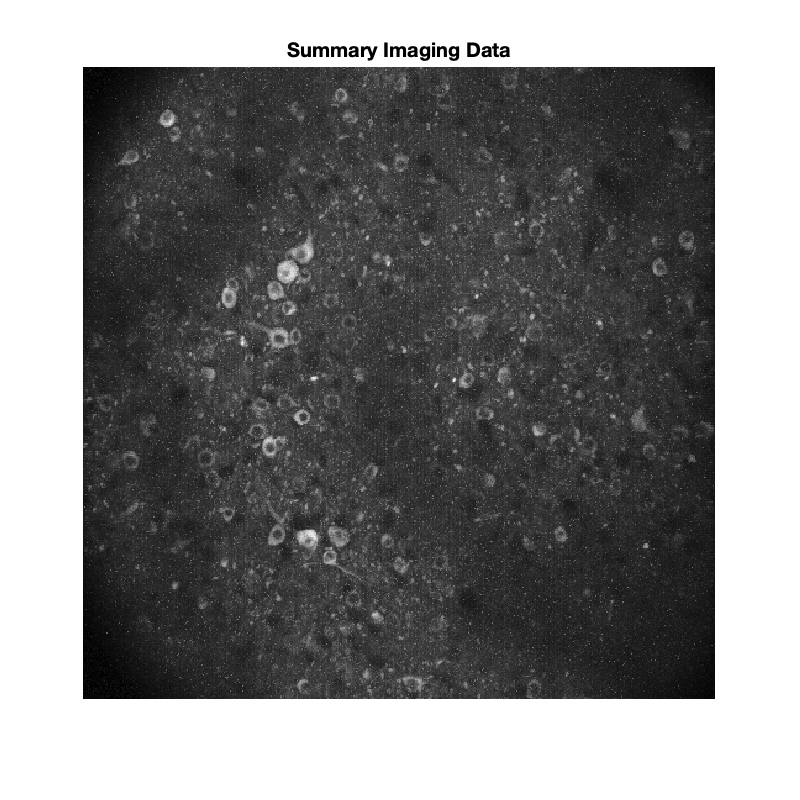

video = get_tif_video(session_key);
max_image = max(video,[],3);
scaled_image = rescale(max_image);
bright_image = imlocalbrighten(scaled_image,0.3,'AlphaBlend',true);

imshow(bright_image)
set(gcf,'position',[0,0,800,800])
title('Summary Imaging Data', 'FontSize', 20)

## Running an imaging session through the pipeline

- **Populate Scan (previous step)**

- **Populate ScanInfo **

- `imaging.ScanInfo: ``Metadata of the imaging acquisition. *(Calculate bleaching to filter tif videos that are not good to process).`

session_key.session_date = '2021-03-01';
%populate(imaging.ScanInfo, session_key)
fetch(imaging.ScanInfo & session_key, '*')

ans = struct with fields:
             subject_fullname: 'testuser_imaging_pipe1'
                 session_date: '2021-03-01'
               session_number: 0
               file_name_base: '/mnt/bucket/PNI-centers/Bezos/RigData/scope/bay3/testuser/imaging/testuser_imaging_pipe1/20210301/imaging_pipe1_20210321_RSMP_125um_41mW_zoom2p2_00001_00001.tif'
                   scan_width: 512
                  scan_height: 512
                     acq_time: '2021-03-01 00:00:00'
                     n_depths: 0
                  scan_depths: 0
                   frame_rate: 29.1333
            inter_fov_lag_sec: 0.0020
                 frame_ts_sec: [6000×1 double]
                power_percent: 15
                     channels: 1
                 cfg_filename: ' 'C:\LocalData\ScanImageConfig\sakoay_si2015.cfg'↵scanimage.SI.hConfigurationSaver.cfg'
                 usr_filename: ' 'C:\LocalData\ScanImageConfig\sakoay_si2015.usr'↵scanimage.SI.hConfigurationSaver.usr'
                   fast_z_l

- `imaging.FieldOfView: ``Meta-info about specific FOV on imaging session. (2/3 photon: single FOV, mesoscope: multiple FOV).`

fetch(imaging.FieldOfView & session_key, '*')

ans = struct with fields:
           subject_fullname: 'testuser_imaging_pipe1'
               session_date: '2021-03-01'
             session_number: 0
                        fov: 1
              fov_directory: '/mnt/bucket/PNI-centers/Bezos/RigData/scope/bay3/testuser/imaging/testuser_imaging_pipe1/20210301'
                   fov_name: ''
                  fov_depth: 0
              fov_center_xy: 0
                fov_size_xy: 0
       fov_rotation_degrees: 0
    fov_pixel_resolution_xy: 0
    fov_discrete_plane_mode: 0


**         3. Populate motion correction**

Let's check first methods available for running:

**imaging.McMethod: **List of implemented methods for motion correction

imaging.McMethod

ans = Object imaging.McMethod

 :: available motion correction method ::

           MC_METHOD           correlation_type    tranformation_type
    _______________________    ________________    __________________

    {'LinearNormalized'   }     {'Normalized'}       {'Linear'   }   
    {'NonLinearNormalized'}     {'Normalized'}       {'NonLinear'}   

2 tuples (0.465 s)


Let's check all parameters for each method

- `imaging.McParameter: ``List of parameters for each motion correction method`

imaging.McParameter

ans = Object imaging.McParameter

 :: parameter definition for a motion correction method ::

           MC_METHOD              MC_PARAMETER_NAME       mc_parameter_description
    _______________________    _______________________    ________________________

    {'LinearNormalized'   }    {'mc_black_tolerance' }           {0×0 char}       
    {'LinearNormalized'   }    {'mc_extra_param'     }           {0×0 char}       
    {'LinearNormalized'   }    {'mc_max_iter'        }           {0×0 char}       
    {'LinearNormalized'   }    {'mc_max_shift'       }           {0×0 char}       
    {'LinearNormalized'   }    {'mc_median_rebin'    }           {0×0 char}       
    {'LinearNormalized'   }    {'mc_stop_below_shift'}           {0×0 char}       
    {'NonLinearNormalized'}    {'mc_black_tolerance' }           {0×0 char}       
    {'NonLinearNormalized'}    {'mc_max_iter'        }  

How many sets for each method ??

- `imaging.McParameterSet: ``List of parameter sets for given motion correction methods`

imaging.McParameterSet

ans = Object imaging.McParameterSet

 :: pointer for a pre-saved set of parameter values ::

         MC_METHOD          MC_PARAMETER_SET_ID
    ____________________    ___________________

    {'LinearNormalized'}             1         

1 tuples (1.27 s)


Let's check the values for each parameter for each set for  LinearNormalized method

- `imaging.McParameterSetParameter: ``Values of the parameters for a given motion correction method and a given set of parameters`

fetch(imaging.McParameterSetParameter, '*')

ans = 6×1 struct array with fields:
    mc_method
    mc_parameter_set_id
    mc_parameter_name
    mc_parameter_value


Finally, process motion correction data

run_mc_session_key = session_key;
run_mc_session_key.mc_method = 'LinearNormalized';
run_mc_session_key.mc_parameter_set_id = 1;
% populate(imaging.MotionCorrection, run_mc_session_key)
fetch(imaging.MotionCorrection & run_mc_session_key, '*')

ans = struct with fields:
        subject_fullname: 'testuser_imaging_pipe1'
            session_date: '2021-03-01'
          session_number: 0
                     fov: 1
               mc_method: 'LinearNormalized'
     mc_parameter_set_id: 1
    mc_results_directory: '/mnt/bucket/PNI-centers/Bezos/RigData/scope/bay3/testuser/imaging/testuser_imaging_pipe1/20210301/LinearNormalized_set_1'


#### Check motion correction results

- `imaging.MotionCorrectionWithinFile: ``Within each tif file, x-y shifts for motion registration`

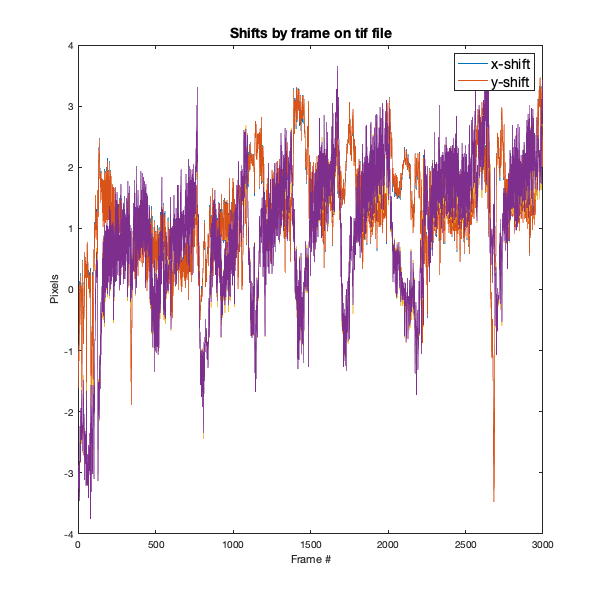

shifts = fetch(imaging.MotionCorrectionWithinFile & run_mc_session_key, 'within_file_x_shifts', 'within_file_y_shifts');
first_file_xshift = shifts(1).within_file_x_shifts;
first_file_yshift = shifts(1).within_file_y_shifts;
plot([first_file_xshift first_file_yshift])
set(gcf,'position',[0,0,600,600])
xlabel('Frame #')
ylabel('Pixels')
legend({'x-shift', 'y-shift'}, "FontSize", 14)
title('Shifts by frame on tif file', "FontSize", 14)

** 4. Populate segmenation**

Let's check first methods available for running:

- `imaging.SegmentationMethod: ``List of implemented methods for segmentation`

methods = fetch(imaging.SegmentationMethod)

methods = 2×1 struct array with fields:
    seg_method


Let's check sets of parameters for selected method

- `imaging.McParameterSetParameter: ``Values of the parameters for a given segmentation method and a given set of parameters`

seg_method_key = struct();
seg_method_key.seg_method = 'cnmf';
[table_diff_params, struct_common] = imaging.utils.compare_parameters(imaging.SegParameterSetParameter, seg_method_key)

table_diff_params = 4×3 table
    set_id    chunks_auto_select_behav    cnmf_files_per_chunk
    ______    ________________________    ____________________

      1                false                       16         
      2                false                        2         
      3                false                       50         
      4                true                        50         


struct_common = struct with fields:
             chunks_auto_select_bleach: 1
    chunks_break_nonconsecutive_blocks: 1
     chunks_min_num_consecutive_blocks: 2
             chunks_towers_bias_thresh: 0.4000
            chunks_towers_max_frac_bad: 0.2000
            chunks_towers_min_n_trials: 30
             chunks_towers_perf_thresh: 0.6000
           chunks_visguide_bias_thresh: 0.4000
          chunks_visguide_max_frac_bad: 0.2000
          chunks_visguide_min_n_trials: 10
           chunks_visguide_perf_thresh: 0.8000
                cnmf_default_timescale: 10
                cnmf_dff_rectification: 2
                       cnmf_frame_rate: 12.3000
                cnmf_max_centroid_dist: 1
                  cnmf_min_dist_pixels: 1
                   cnmf_min_num_frames: 2000
             cnmf_min_roi_significance: 3
                   cnmf_min_shape_corr: 0.8500
                   cnmf_num_components: 400
                         cnmf_num_iter: 2
                                c

Add a new set of parameters to run

- `imaging.SegParameterSet: ``List of sets for given methods`

seg_method_key = struct();
seg_method_key.seg_method = 'cnmf';
seg_method_key.seg_parameter_set_id = 4;
% Go to file SegParameterSetParameter and set all parameters with desired values
insert(imaging.SegParameterSet, seg_method_key)

For now, we will delete this new set

seg_method_key = struct();
seg_method_key.seg_method = 'cnmf';
seg_method_key.seg_parameter_set_id = 4;
del(imaging.SegParameterSet & seg_method_key)


ABOUT TO DELETE:
       1 tuples from `u19_imaging`.`seg_parameter_set` (manual)
      38 tuples from `u19_imaging`.`seg_parameter_set__parameter` (manual)

Deleting from imaging.SegParameterSetParameter
Deleting from imaging.SegParameterSet
committed


Finally, process segmentation data

run_seg_session_key = run_mc_session_key;
run_seg_session_key.seg_method = 'cnmf';
run_seg_session_key.seg_parameter_set_id = 1;
% populate(imaging.Segmentation, run_seg_session_key)
fetch(imaging.Segmentation & run_seg_session_key, '*')

ans = struct with fields:
                subject_fullname: 'testuser_imaging_pipe1'
                    session_date: '2021-03-01'
                  session_number: 0
                             fov: 1
                       mc_method: 'LinearNormalized'
             mc_parameter_set_id: 1
                      seg_method: 'cnmf'
            seg_parameter_set_id: 1
                      num_chunks: 1
           cross_chunks_x_shifts: 0
           cross_chunks_y_shifts: 0
    cross_chunks_reference_image: [512×512 single]
           seg_results_directory: '/mnt/bucket/PNI-centers/Bezos/RigData/scope/bay3/testuser/imaging/testuser_imaging_pipe1/20210301/LinearNormalized_set_1/cnmf_set_1'


#### Check segmentation results

- `imaging.SegmentationRoi: ``Metainformation and pixel masks for each ROI`

- `imaging.SegmentationRoiMorphologyAuto: ``Automatic morphological classification of the ROIs`

summary_image     = get_summary_image(run_seg_session_key);
shape_variance    = get_shape_variance();

roi_info          = fetch(imaging.SegmentationRoi & run_seg_session_key, '*');
roi_morph_info    = fetch(imaging.SegmentationRoiMorphologyAuto & run_seg_session_key, '*');
roi_morph_info_show = roi_morph_info(1:3:15)

roi_morph_info_show = 5×1 struct array with fields:
    subject_fullname
    session_date
    session_number
    fov
    mc_method
    mc_parameter_set_id
    seg_method
    seg_parameter_set_id
    roi_idx
    morphology


ROI_TYPES = RegionMorphology.all();
colors = [[1 0.7 0];[0 1 0];[1 0 1];[1 1 0];[0 1 1];[0 0 1];[1 0 0]];

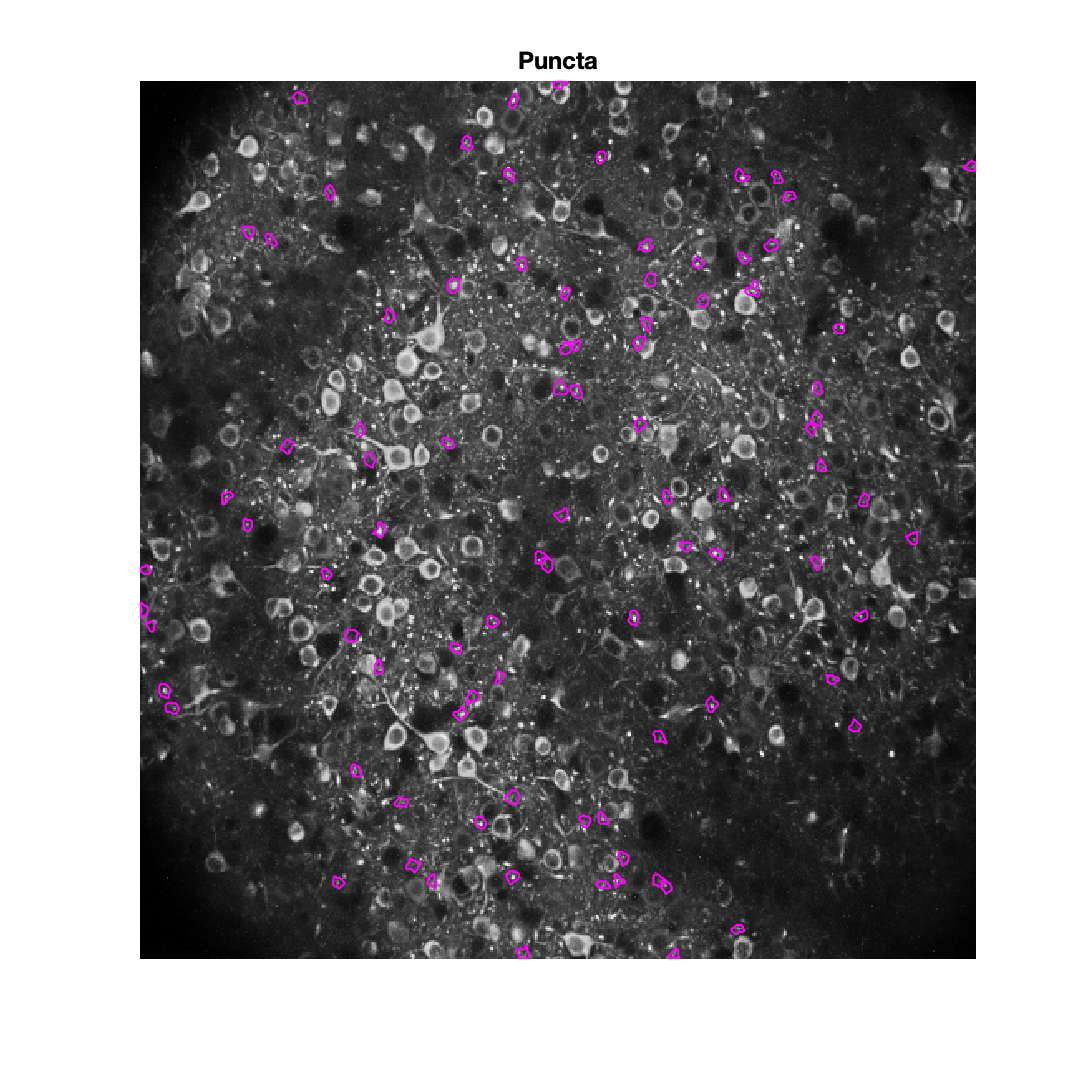

morphology_sel =3;
shape_variance_sel = 0.045;
sel_type = ROI_TYPES{morphology_sel};
figure;
imagesc(summary_image);
hold on;
colormap gray
set(gcf,'position',[0,0,1200,1200])
title(sel_type,'FontSize',24)
%Get matching morpholgy rois
idx_type = matches({roi_morph_info.morphology},sel_type);
idx_variance = shape_variance < shape_variance_sel;
spatial = {roi_info.roi_spatial};
spatial = spatial(idx_type & idx_variance);

sa = find(idx_type & idx_variance);
%Plot boundaries of all ROIs
for iROI = 1:size(spatial,2)
    
    borders = bwboundaries(spatial{iROI});
    for i=1:length(borders)
        boundary = borders{i};
        plot(boundary(:,2), boundary(:,1), 'Color', colors(morphology_sel,:), 'LineWidth', 2)
    end
    
    
end
hold off
axis off

**Check trace results**

- `imaging.Trace: ``Stores activity traces for each ROI`

cell_boxes    = get_cell_boxes();
trace_info    = fetch(imaging.Trace & run_seg_session_key, 'dff_roi', 'spiking');

**____**

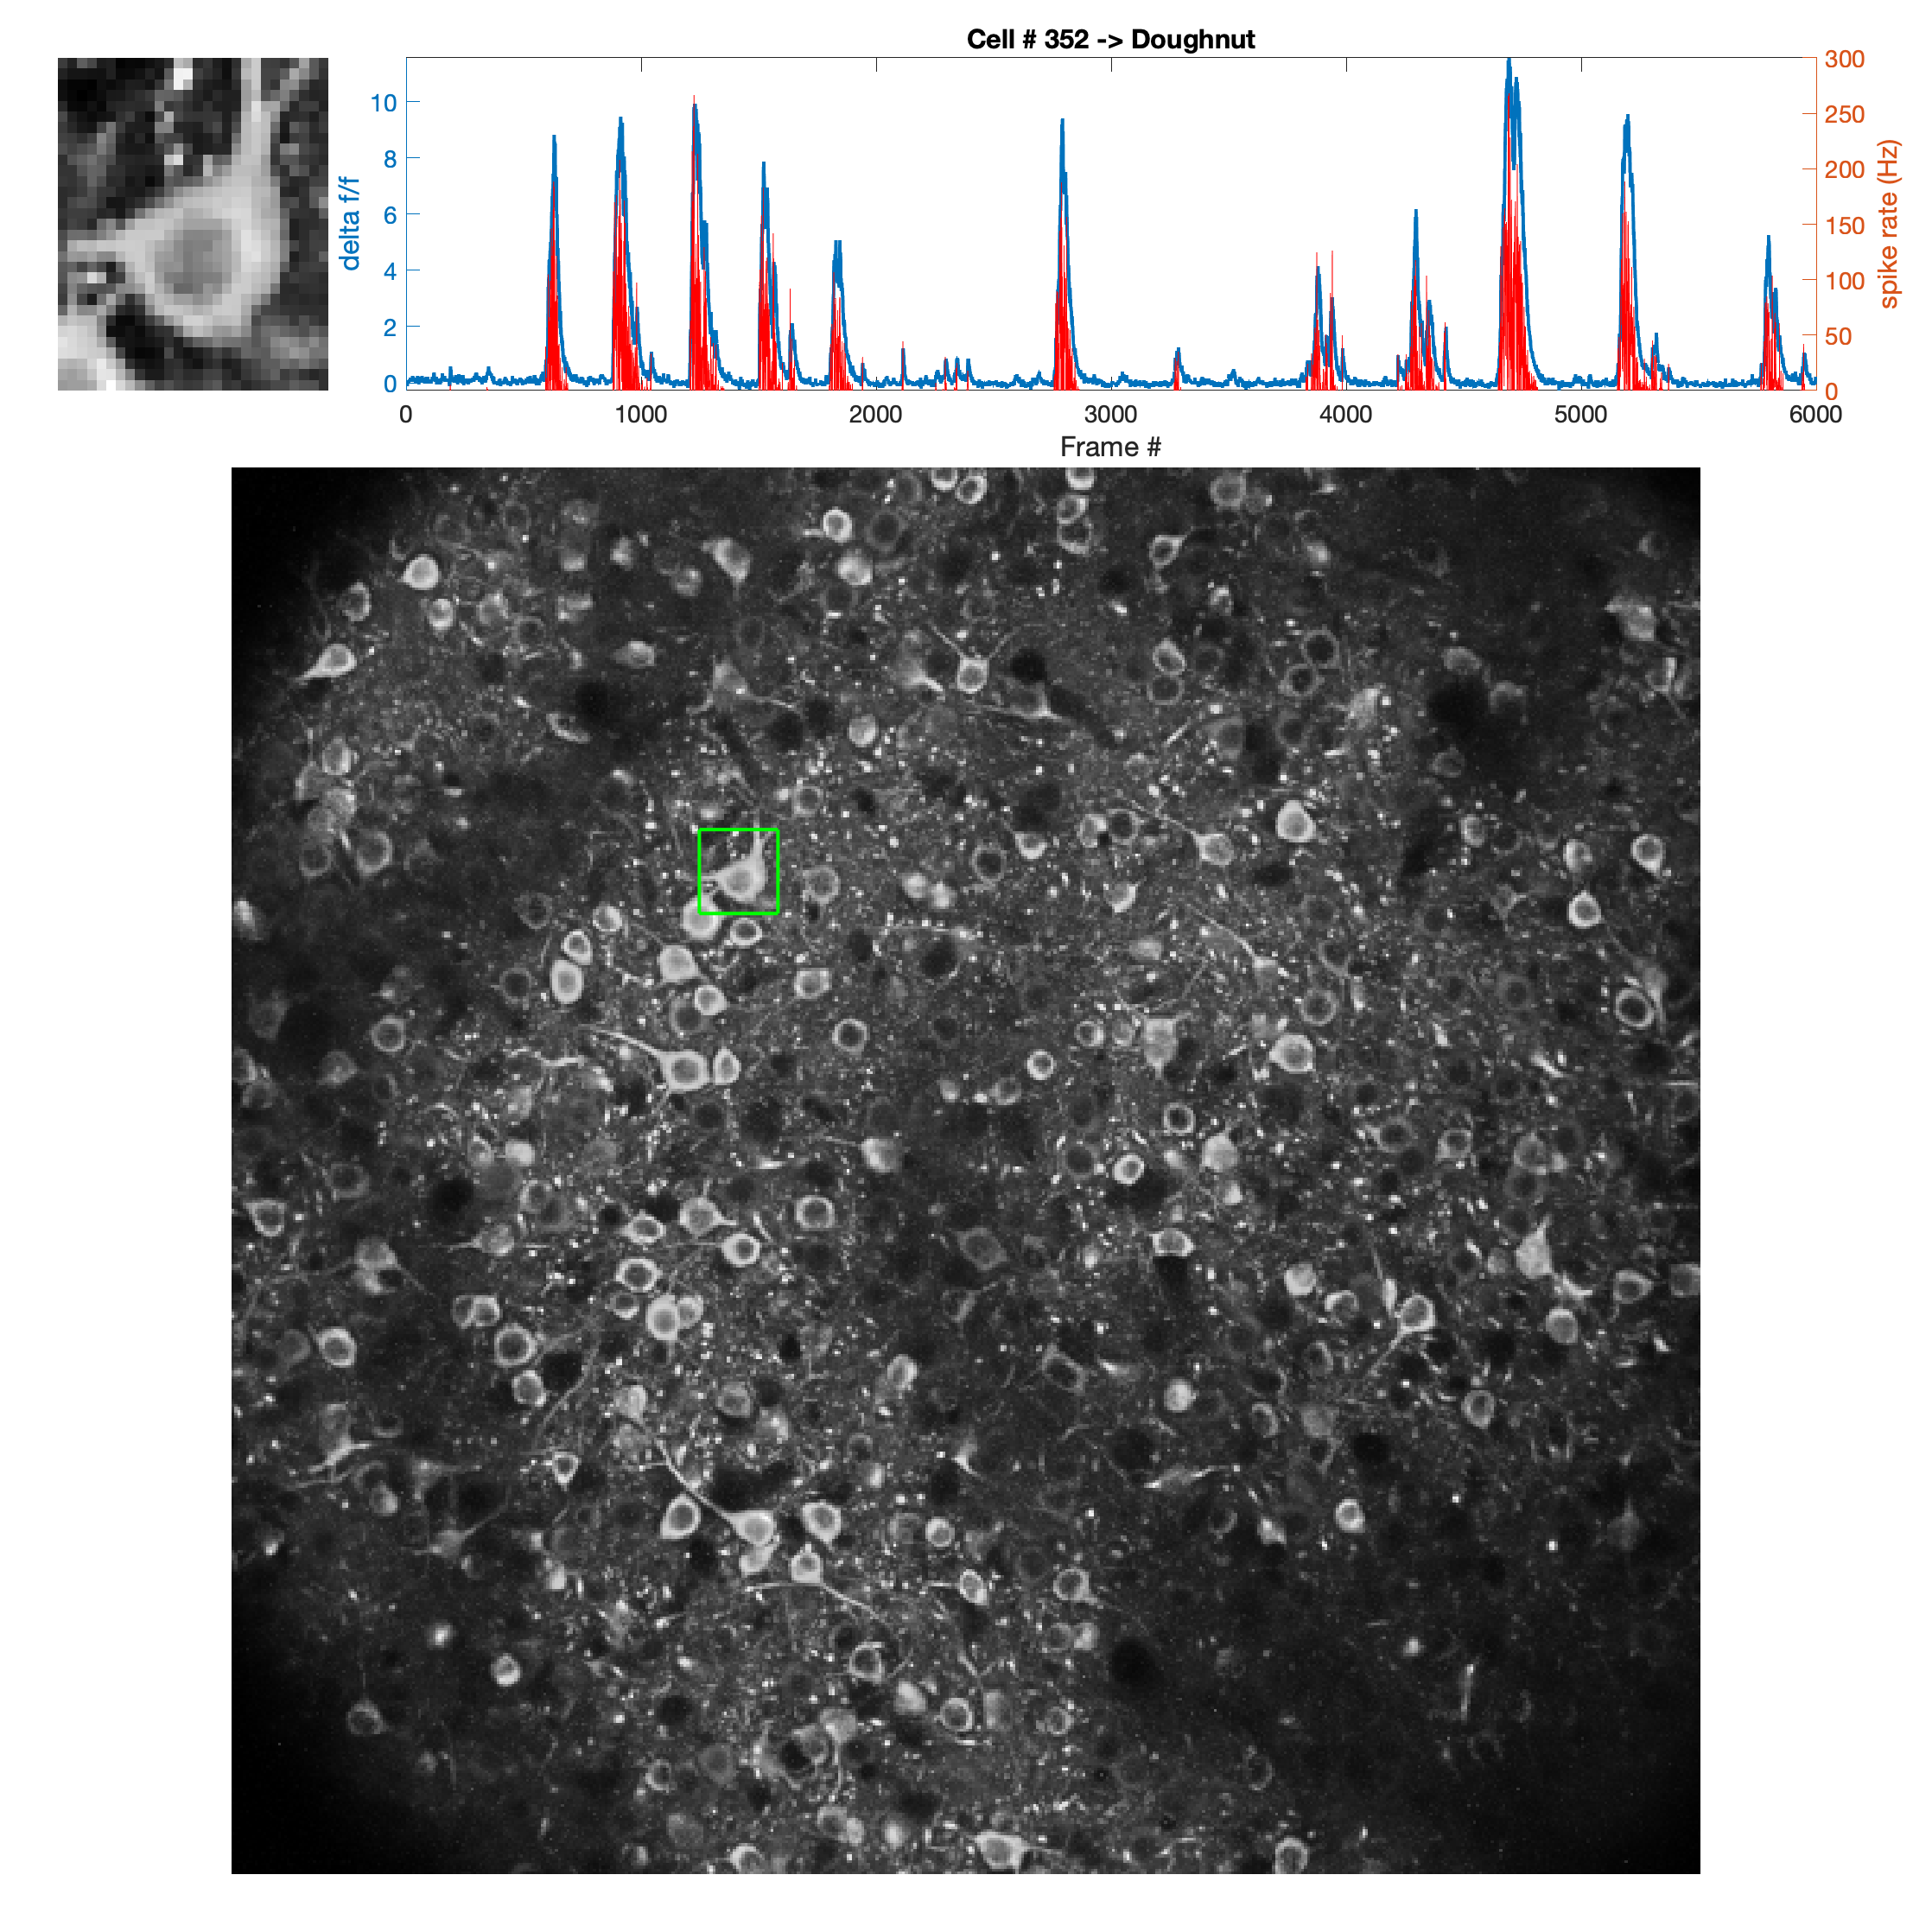

% cool idxs  352 353, 1252, 1279 1169
idx_cell      = 352;
current_box     = cell_boxes(idx_cell,:);
cols_idx        = current_box(1)+1:current_box(1)+1+current_box(3);
rows_idx        = current_box(2)+1:current_box(2)+1+current_box(4); 
box_summary_image = summary_image(rows_idx,cols_idx);
figure
subaxis(5,6,1,'Spacing',0.0,'Margin',0.02,'Padding',0.01);
imagesc(box_summary_image);
axis off
colormap gray
subaxis(5,6,2:6,'Spacing',0.0,'Margin',0.02,'PaddingLeft',0.03, 'PaddingRight',0.04,'PaddingBottom',0.01);
yyaxis right
hold on
plot(trace_info(idx_cell).spiking, 'r')
ylabel('spike rate (Hz)', "FontSize", 16)
set(gca, 'FontSize',14)
yyaxis left
plot(trace_info(idx_cell).dff_roi, 'LineWidth',2)
set(gca, 'FontSize',14)
ylabel('delta f/f', "FontSize", 16)
title(['Cell # ' num2str(idx_cell) ' -> ' roi_morph_info(idx_cell).morphology])
%axis off
xlabel('Frame #', "FontSize", 16)
subaxis(5,6,7:30,'Spacing',0.0,'Margin',0.02,'PaddingLeft',0.1, 'PaddingRight',0.1, 'PaddingTop', 0.03);
imagesc(summary_image)
axis off
colormap gray
line([cols_idx(1), cols_idx(end)], [rows_idx(1), rows_idx(1)], 'Color', [0 1 0], 'LineWidth',2)
line([cols_idx(1), cols_idx(end)], [rows_idx(end), rows_idx(end)], 'Color', [0 1 0], 'LineWidth',2)
line([cols_idx(1), cols_idx(1)], [rows_idx(1), rows_idx(end)], 'Color', [0 1 0], 'LineWidth',2)
line([cols_idx(end), cols_idx(end)], [rows_idx(1), rows_idx(end)], 'Color', [0 1 0], 'LineWidth', 2)
set(gcf,'position',[0,0,1800,1800])

**Extra information:**

- `imaging.SegmentationChunks: ``Registration between different segmentation chunks within a recording`

fetch(imaging.SegmentationChunks & run_seg_session_key, '*')

ans = struct with fields:
         subject_fullname: 'testuser_imaging_pipe1'
             session_date: '2021-03-01'
           session_number: 0
                      fov: 1
                mc_method: 'LinearNormalized'
      mc_parameter_set_id: 1
               seg_method: 'cnmf'
     seg_parameter_set_id: 1
    segmentation_chunk_id: 1
            tif_file_list: {2×1 cell}
      imaging_frame_range: [1 6000]
        region_image_size: [503 504]
     region_image_x_range: [5 508]
     region_image_y_range: [5 507]


back_info = fetch(imaging.SegmentationBackground & run_seg_session_key, '*')

back_info = struct with fields:
         subject_fullname: 'testuser_imaging_pipe1'
             session_date: '2021-03-01'
           session_number: 0
                      fov: 1
                mc_method: 'LinearNormalized'
      mc_parameter_set_id: 1
               seg_method: 'cnmf'
     seg_parameter_set_id: 1
    segmentation_chunk_id: 1
       background_spatial: [503×504 double]
      background_temporal: [1×6000 single]


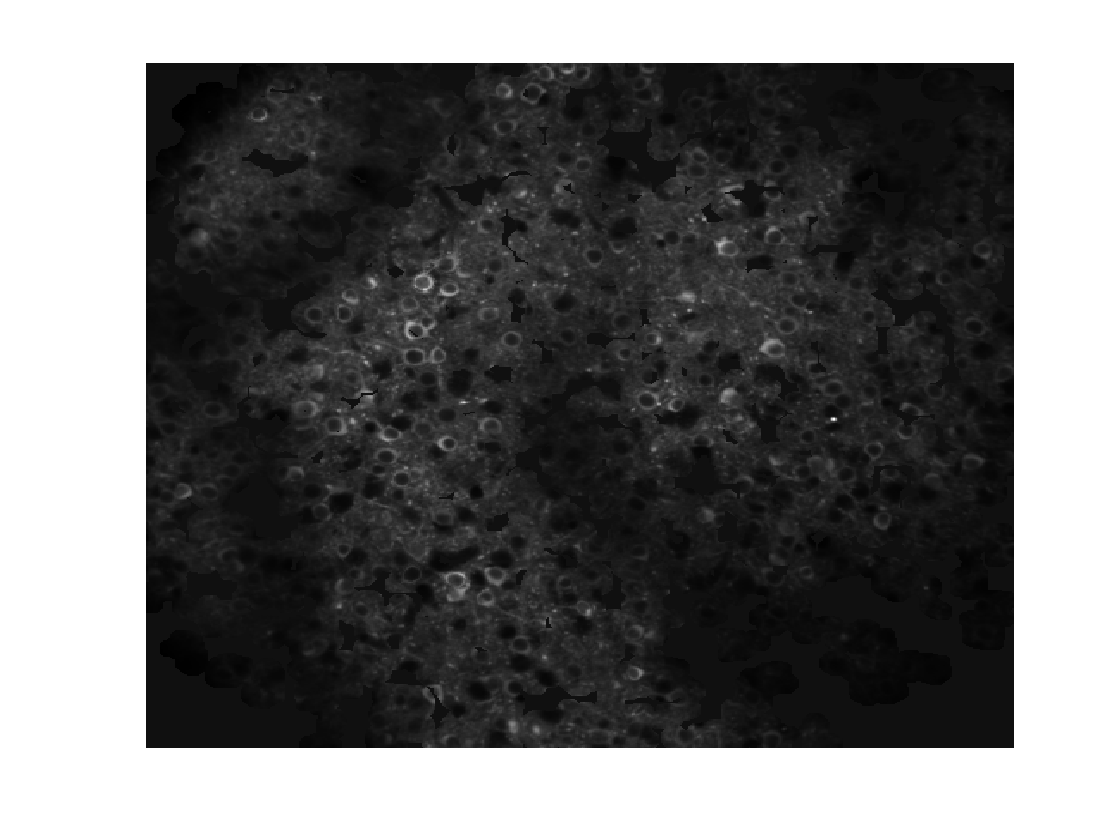

figure
imagesc(back_info.background_spatial)
colormap gray
axis off

## **Table description appendix:**

**Prerequisites**

- `acquisition.Session: ``Basic session information from behavioral training.`

**"Scan" Tables**

- `imaging.Scan: ``Relationship between session & imaging path.`

- `imaging.ScanInfo: ``Metadata of the imaging acquisition. *(Calculate bleaching to filter tif videos that are not good to process).`

- `imaging.FieldOfView: ``Meta-info about specific FOV on imaging session. (2/3 photon: single FOV, mesoscope: multiple FOV).`

- `imaging.FieldOfViewFile: ``List of files per Field of View`

**Motion Correction Tables**

- **imaging.McMethod: **List of implemented methods for motion correction

- `imaging.McParameter: ``List of parameters for each motion correction method`

- `imaging.McParameterSet: ``List of parameter sets for given motion correction methods`

- `imaging.McParameterSetParameter: ``Values of the parameters for a given motion correction method and a given set of parameters`

- `imaging.MotionCorrection: ``Handles a motion correction process for a field of view with a given method and given parameters.`

- `imaging.MotionCorrectionAcrossFiles: ``Across tif files, x-y shifts for motion registration`

- `imaging.MotionCorrectionWithinFile: ``Within each tif file, x-y shifts for motion registration`

**Segmentation Tables**

- `imaging.SegmentationMethod: ``List of implemented methods for segmentation`

- `imaging.SegParameter: ``List of parameters for each segmentation method`

- `imaging.SegParameterSet: ``List of parameter sets for given segmentation methods`

- `imaging.McParameterSetParameter: ``Values of the parameters for a given segmentation method and a given set of parameters`

- `imaging.Segmentation: ``Handles a segmentation process for a motion correction processed session with a given method and given parameters.`

- `imaging.SegmentationChunks: ``Registration between different segmentation chunks within a recording`

- `imaging.SegmentationBackground: ``Handles a segmentation process for a motion correction processed session with a given method and given parameters.`

- `imaging.SegmentationRoi: ``Metainformation and pixel masks for each ROI`

- `imaging.SegmentationRoiMorphologyAuto: ``Automatic morphological classification of the ROIs`

- `imaging.SegmentationRoiMorphologyManual: ``Manual morphological classification of the ROIs`

- `imaging.Trace: ``Activity traces for each ROI found in Segmentation process`

`Auxiliar Tables`

- `imaging.SyncImagingBehavior: ``Relationship between virmen blocks, trials & iteration# with frame on imaging tiff files.`